# Modello di Hammerstein-Wiener per la dinamica della coppia di un motore spark-ignition

% L'obiettivo è quello di modellare la dinamica della coppia non lineare di
% un motore spark ignition tramite Hammerstein-Wiener

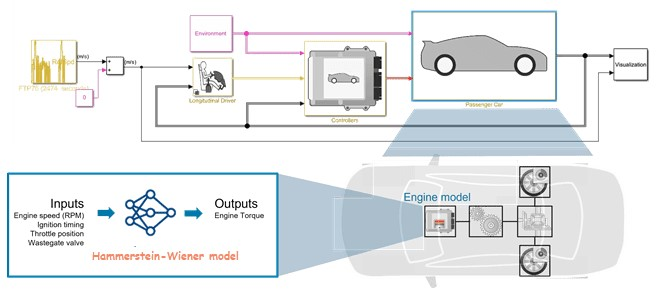

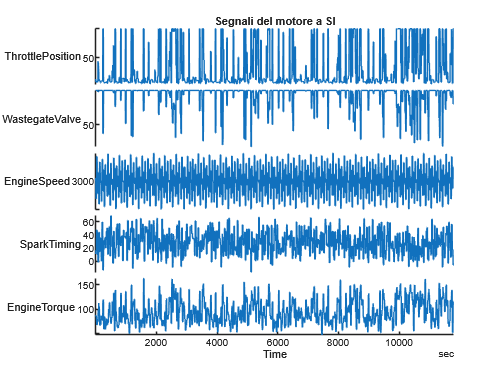

load SIEngineData.mat 
% Mosto i dati del motore nel tempo
stackedplot(IOData)
title('Segnali del motore a SI')

% in questo dataset sono presenti oltre 100k osservazioni di 5 variabili
% effettuate a 10 Hz:
% Throttle position (degrees)
% Wastegate valve area (aperture percentage)
% Engine speed (RPM)
% Spark timing (degrees)
% Engine torque (N m)
% Divido i dati in due set uno di stima e uno di validazione
eData = IOData(1:6e4,:);     % stima
vData = IOData(6e4+1:end,:); % validazione
% Effettuo un downsampling dei dati di un fattore 10 per velocizzare il
% training del modello
eDataD = idresamp(eData,[1 10]); 
vDataD = idresamp(vData,[1 10]);
eDataD.Properties.TimeStep

ans = duration
   1 sec


% Effettuo una prima simulazione utilizzando un modello lineare per stimare
% le caratteristiche più importanti del modello da utilizzare per il caso
% non lineare
% Utilizzo il comando ssest che permette di trovare il valore ottimo in un
% certo range
% Vado a specificare le opzioni che mi permettano di minimizzare l'errore
% di simulazione, l'orizzonte, il numero massimo di iterazioni e l'ordine
% del modello
ssOpt = ssestOptions(Focus="simulation");
ssOpt.N4Horizon = [15 0 26]; %[r sy su]->r max orizzonte di predizione, sy e su output e input passati per effettuare la predizione
ssOpt.SearchOptions.MaxIterations = 200;
Order = 7;
% Stimo il modello di stato utilizzando i dati di stima
Inputs = ["ThrottlePosition","WastegateValve","EngineSpeed","SparkTiming"];
Output = "EngineTorque";
linsys = ssest(eDataD, Order,'Feedthrough',true(1,4),'Ts',1,'DisturbanceModel','none','InputName',Inputs,'OutputName',Output,ssOpt)


linsys =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
              x1         x2         x3         x4         x5         x6         x7
   x1     0.6307     0.3216    -0.2104     0.0621   -0.08057   -0.06688    -0.4296
   x2    -0.2057    -0.3095     0.4587   -0.07681     0.1713     0.5015      1.665
   x3   -0.02398    -0.1231     0.3411     0.7639     0.6176    0.07823       1.12
   x4   -0.03332    0.04544    -0.9544    -0.2606     0.3623    -0.5218    -0.1301
   x5    0.06289    -0.3276     0.2222     -0.419     0.2827     0.4606    -0.1373
   x6     0.1268     0.2479    -0.1423    -0.1647     -0.169     0.2188      -1.64
   x7   -0.04426    0.05109    0.08225  -0.005721    -0.1281     0.1702      1.033
 
  B = 
       ThrottlePosi  WastegateVal   EngineSpeed   SparkTiming
   x1     -0.002453      -0.01188     0.0003596      0.003926
   x2       0.02644        0.1191     -0.003484      -0.03948


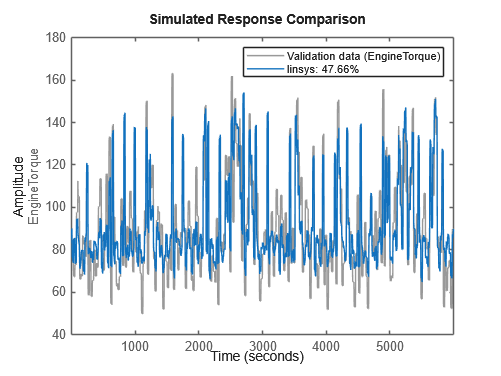

% Vado a fare una comparazione tra il modello lineare appena simulato e
% quello utilizzato per il training
compare(eDataD, linsys)


% E' possibile osservare come questo modello riesca ad emulare solo il 50%
% del Normalized Root Mean Error, ma ci da una buona base di partenza per
% sviluppare il modello di Hammerstein-Wiener
% Utilizzo un regressore chiamato Sigmoid Network che utilizza delle sigmoidi
% per approssimare il modello non lineare
% Utilizzo 3 sigmoidi che sono in grado di approssimare meglio il modello,
% Questo risultato è stato ottenuto tramite prove ripetute
NonlinearFcn = idSigmoidNetwork(3,false,false)

NonlinearFcn = Sigmoid Network

 Nonlinear Function: Sigmoid network with 3 units
 Linear Function: not in use
 Output Offset: not in use

    NonlinearFcn: 'Sigmoid units and their parameters'
       LinearFcn: 'Linear function parameters

% Creo il modello di Hammerstein utilizzando una funzione
% costruttrice di modelli che utilizza sia i dati forniti dal modello
% lineare che quelli forniti dal modello non lineare
HammersteinModel = idnlhw(linsys, NonlinearFcn, [])


HammersteinModel =

Hammerstein-Wiener model with 1 output and 4 inputs

Linear transfer function matrix corresponding to the orders:
   nb = [8 8 8 8]
   nf = [7 7 7 7]
   nk = [0 0 0 0]

Input nonlinearities:
  Input 1:  Sigmoid network with 3 units
  Input 2:  



% Fisso i coefficienti del denominatore al valore attuale per fissare i
% poli del sistema
HammersteinModel.Ffree = false;
% Per il training del modello utilizzo il metodo di ricerca lsqnonlin senza
% normalizzazione dei segnali di I/O
% Configuro le opzioni di training
nlhwopt = nlhwOptions('Display','on');
nlhwopt.SearchMethod = 'lsqnonlin';
nlhwopt.SearchOptions.MaxIterations = 300;
% Decido di non normalizzare gli I/O
nlhwopt.Normalize = false;
% Stimo i parametri di questo modello appena creato affinché possa fittare
% i dati di eDataD utilizzando il comando nlhw
HammersteinModel = nlhw(eDataD,HammersteinModel,nlhwopt)


HammersteinModel =

Hammerstein-Wiener model with 1 output and 4 inputs

Linear transfer function matrix corresponding to the orders:
   nb = [8 8 8 8]
   nf = [7 7 7 7]
   nk = [0 0 0 0]

Input nonlinearities:
  Input 1:  Sigmoid network with 3 units
  Input 2:  

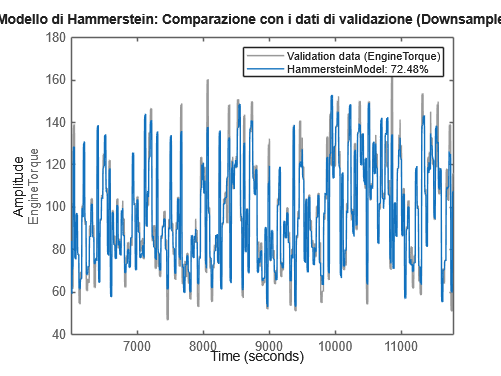

% Vado a fare una valutazione della bontà del modello comparando la
% risposta simulata a quella misurata nei dataset di validazione

compare(vDataD,HammersteinModel)  % comaparazione con i dati di validazione
title('Modello di Hammerstein: Comparazione con i dati di validazione (Downsampled)')


% Vado ora ad identificare un modello che utilizza funzioni lineari a
% tratti sia per l'input che per l'output non lineare
% Per fare in modo che il modello non sia peggiore di quello semplicemente
% lineare devo fare in modo che i parametri lineari non possano cambiare
PWLin = idPiecewiseLinear(12); % input non lineare
PWLout = idPiecewiseLinear(3); % output non lineare
HWModel = idnlhw(linsys, PWLin, PWLout); 
% Blocco le variabili lineari
HWModel.Bfree = false;
HWModel.Ffree = false;
% Inserisco le opzioni di stima
nlhwopt = nlhwOptions('Display','on');
nlhwopt.SearchMethod = 'lm';
nlhwopt.SearchOptions.MaxIterations = 100;
HWModel = nlhw(eDataD,HWModel,nlhwopt)


HWModel =

Hammerstein-Wiener model with 1 output and 4 inputs

Linear transfer function matrix corresponding to the orders:
   nb = [8 8 8 8]
   nf = [7 7 7 7]
   nk = [0 0 0 0]

Input nonlinearities:
  Input 1:  Piecewise linear with 12 breakpoints
  Input 2:  Piecewise linear with 12 breakpoints
  Input 3:  

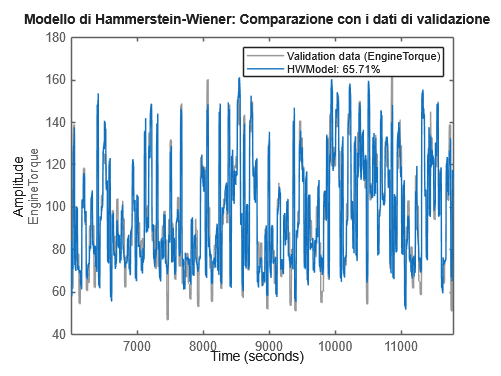

% Vado a fare una valutazione della bontà del modello comparando la
% risposta simulata a quella misurata nei dataset di validazione
compare(vDataD,HWModel)  % compare against validation data
title('Modello di Hammerstein-Wiener: Comparazione con i dati di validazione')

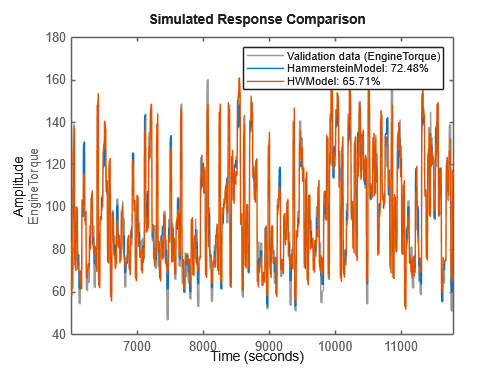


% Vado a comparare il modello creato da me con quello di HW proposto da
% matlab
compare(vDataD,HammersteinModel,HWModel)